## Reconstrucción mediante el FOH No-causal

### Primero defino el retenedor FOH causal:

function y = foh_causal(t)
  y = (t >= 0 & t < 1) .* (1 + t) - (t >= 1 & t < 2) .* (t - 1);
end

function y = foh_no_causal(t)
  y = (t >= -1 & t < 0) .* (1 + t) - (t >= 0 & t < 1) .* (t - 1);
end

function y = ideal(t)
  y = sinc(t);
end


Represento su respuesta al impulso y respuesta en frecuencia: 

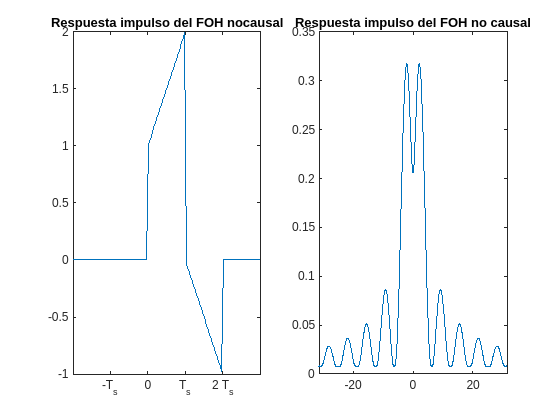

% Periodo de muestreo del retenedor
Ts = 1;
retenedor = @foh_causal;
% retenedor = @foh_no_causal;
% retenedor = @ideal;
% Respuesta al impulso
M = 128;
Ti = -2*Ts; Tf = 3*Ts;
dt = (Tf-Ti)/(M-1);
t = (Ti:dt:Tf);
y = retenedor(t);
% Respuesta en frecuencia
K = 2^12;
w = (0:K-1)*2*pi/K/dt - pi/dt;
Y = fftshift(fft(y, K))/M;

figure(1)
subplot(121)
  plot(t, y);
  title("Respuesta impulso del FOH nocausal");
  xlim([Ti, Tf]);
  xticks([-Ts 0 Ts 2*Ts]);
  xticklabels({"-T_s", "0", "T_s", "2 T_s"});

subplot(122)
  plot(w, abs(Y));
  title("Respuesta impulso del FOH no causal");
  xlim([-5*2*pi/Ts, 5*2*pi/Ts]);

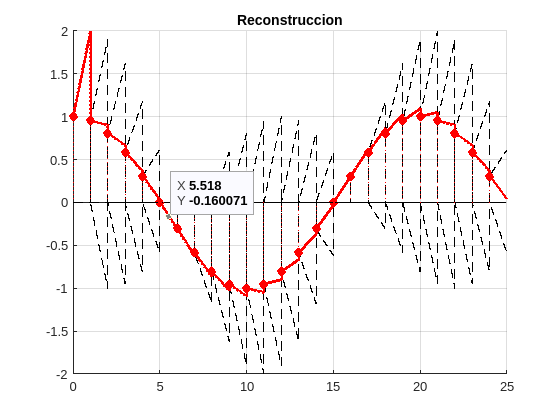

N = 25;
n = [0:N-1]';
Ts = 1; ws = 2*pi/Ts;
T = N*Ts;
dt = 0.001;
t = [0:dt:T-dt]';

wc = pi/(10*Ts);
xc = cos(wc*t);
xd = cos(wc*Ts*n);

x = zeros(size(t));
close all;
figure(1); hold on; grid(); ylim([-2, 2]);
title ('Reconstruccion');
for i=1:N
  ti = (t - (i-1)*Ts)/Ts;
  xi = xd(i)*retenedor(ti);
  x = x + xi;
  plot(t, xi, 'k--');

  j = find(t > (i-1)*Ts, 1);
  plot(t(1:j), x(1:j), 'r:', 'LineWidth', 2);
  stem((i-1)*Ts, xd(i), 'r:', 'MarkerFaceColor', 'r');
  pause(0.1);
end
plot(t, x, 'red', 'LineWidth', 2);